# Drone Payload Structure Design and Analysis

Team 6: Beam Arm and T-Arm Designs

% Task 1: Gather starter assumptions and load material properties

load('droneArmMaterials.mat');
g = 9.81; % gravity m/s^2
motor = 4; % number of motors
thrustMotor = 1; % thrust from 1 motor
baseMass = 1; % mass of body NOT arms
minPayload = 0.5; % minimum payload
TWratio = 2.0; % required ratio of thrust to weight


Task 2: Propose at least two drone arm designs

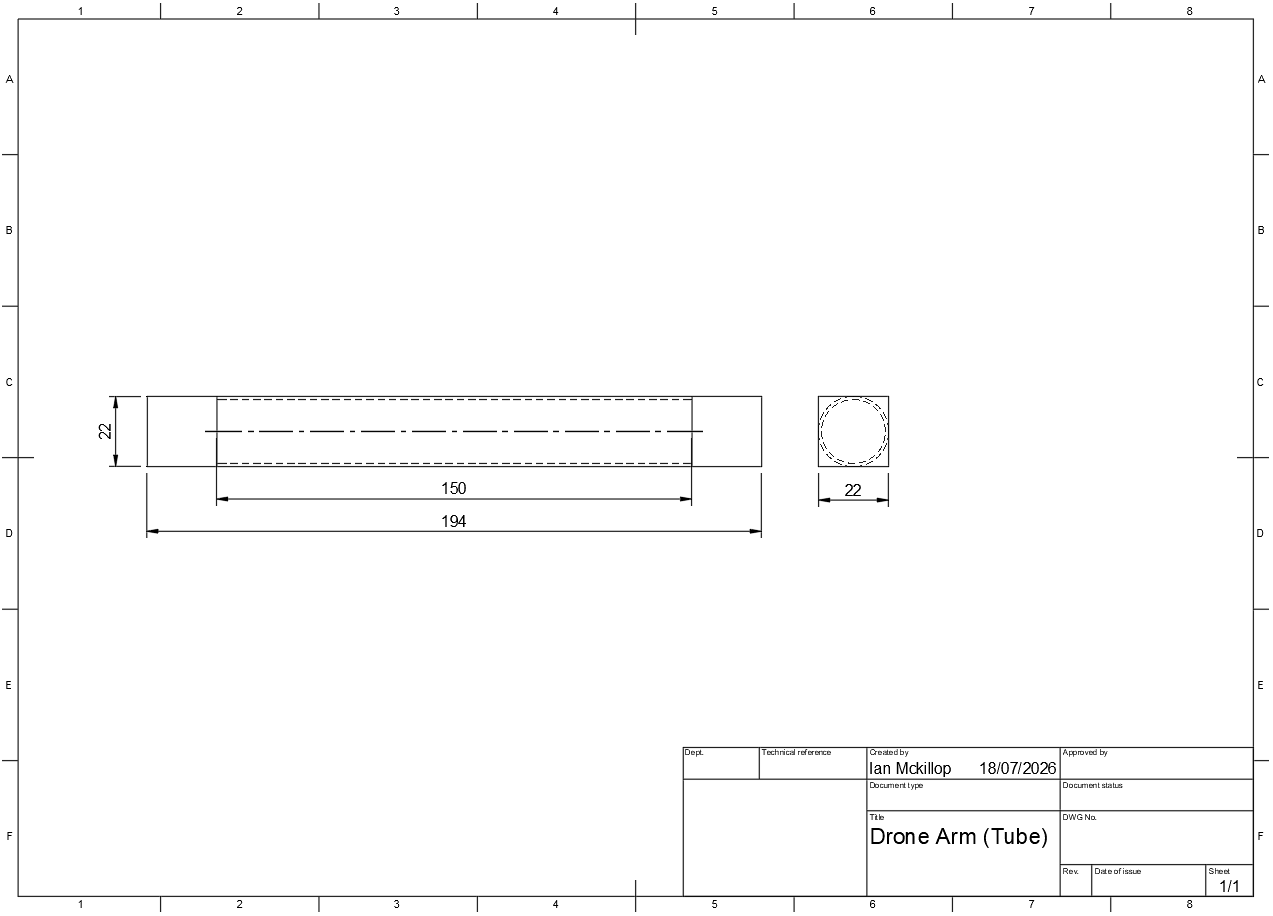

The first drone arm design is that of a hollow tube that connects 2 boxes, which is where the motor & body would mount. 

We chose this drone arm design since it is geometrically quite simple yet should provide a lot of strength through the large tube. This simplicity also makes it much easier to accurately do FEA on.

We guess it will perform quite well under load, due to the large tube connecting the mounting boxes. The first point to fail will probably be the top of the tube connecting directly to the body mounting box, since that's where stress would gather most.

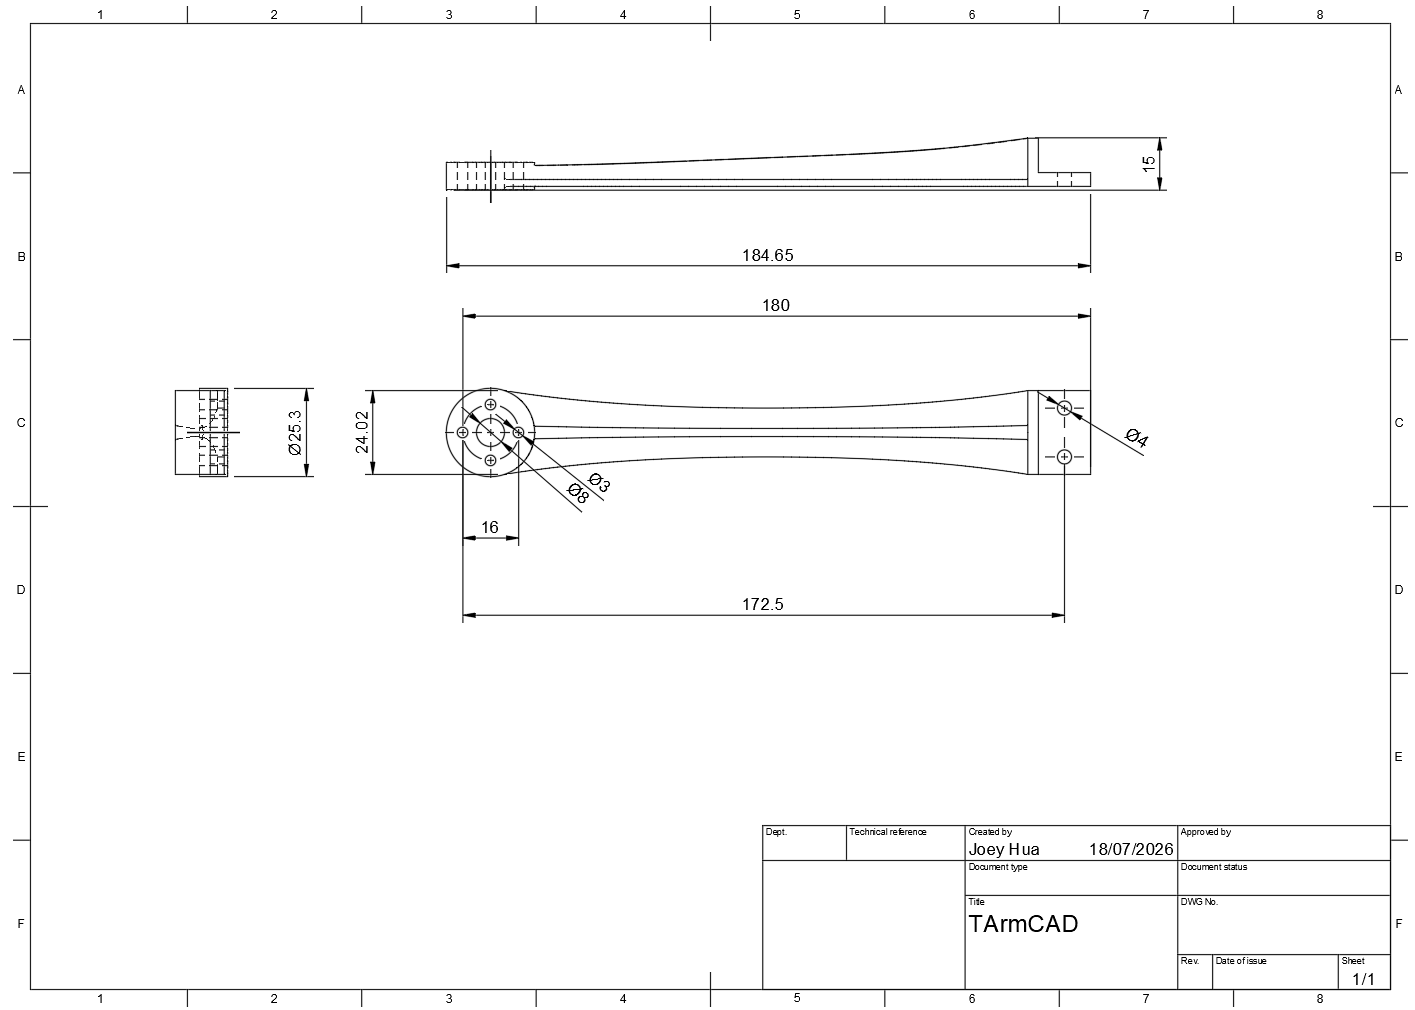

The second drone arm design is that of a T bar that connects the circular motor mount and the body mount. 

We chose this drone arm design because it's a more complicated version of another simple yet effective design. The base of the design is a simple bar connecting the two mounts, but a vertical bar has been added to the underside, strengthening the connection.

We expect this bar will perform worse under load than our first design, but also free up a good amount of material, so the drone can carry a higher maximum payload. It will probably be weakest around where the body mount attaches to the beam arm, since that's where stress will accumulate the most.

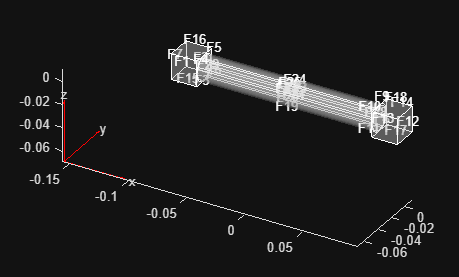

% Task 3: Thrust-to-weight analysis
% Beam Design - Thrust to Weight

volBeamArm = 0.000031192; % taken from Fusion

maxThrust = motor * thrustMotor * g;

beamResults = table();

for m = 1:numel(materials)
    mat = materials(m);

    armMass = volBeamArm * mat.rho_kg_m3;
    totalArmMass = armMass * 4;

    maxPayload = (maxThrust / (TWratio * g)) - baseMass - totalArmMass;

    meetsmin = maxPayload >= minPayload;
    
    beamResults = [beamResults; table(string(mat.name), totalArmMass, maxPayload, meetsmin, 'VariableNames', {'Material', 'ArmMass_kg', 'MaxPayload_kg' ...
        'MeetsMin'})];
end

% clear temporary vars
clearvars m mat armMass totalArmMass maxPayload meetsmin maxThrust

%% T-Arm Design - Thrust to Weight
% This script will help us see the thrust to weight ratio for a truss
% drone arm design.
% Parameters:
% * Thrust must be at least 2x the weight

%Thrust Calculations for T Arm Design
volArm = 0.00001646929; %Pulled from OnShape
maxThrust = motor * thrustMotor * g;

tarmResults = table();

for m = 1:numel(materials)
    mat = materials(m);

    armMass = volArm * mat.rho_kg_m3;
    totalArmMass = armMass * 4;

    maxPayload = (maxThrust / (TWratio * g)) - baseMass - totalArmMass;

    meetsmin = maxPayload >= minPayload;
    tarmResults = [tarmResults; table(string(mat.name), totalArmMass, maxPayload, meetsmin, 'VariableNames', {'Material', 'ArmMass', 'MaxPayload' ...
        'MeetsMin'})];
end

% clear temporary vars
clearvars m mat armMass totalArmMass maxPayload meetsmin maxThrust

%% Task 4: Finite element analysis
%% Beam Design - FEA

tubeGm = fegeometry("Drone Arm (Tube).stl");
tubeGm = scale(tubeGm, 0.001);
tubeMd = femodel(AnalysisType="structuralStatic",Geometry=tubeGm); % create a FEA model object of the drone arm
tubeMd = generateMesh(tubeMd); % generate a mesh of the geometry
pdegplot(tubeMd,FaceLabels="on",FaceAlpha=0.3);

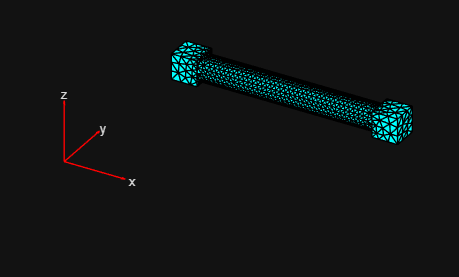

pdemesh(tubeMd); % visualize the mesh

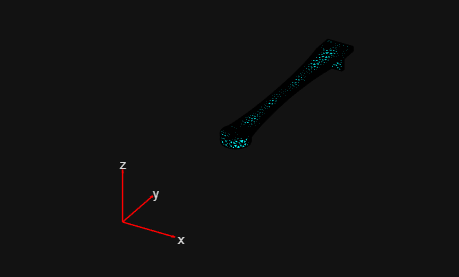


% the code below assigns the faces that connect to the drone body as
% "fixed" so they do not move. 
tubeMd.FaceBC(12) = faceBC(Constraint = 'fixed');
tubeMd.FaceBC(17) = faceBC(Constraint = 'fixed');
tubeMd.FaceBC(18) = faceBC(Constraint = 'fixed');

% the code below applies gravity and the motor thrust/weight to the drone
% arm.
netMotorForce = (1-.105)*g;
tubeMd.FaceLoad(16) = faceLoad(SurfaceTraction=[0 0 (netMotorForce / 0.000484)]);
tubeMd.CellLoad = cellLoad(Gravity=[0 0 -g]);

% the code below formats the data from the fea model and materials provided
% into a table. Type featubeResults into the command window to view the max
% stress, displacement, and factor of safety for the various materials.
featubeResults = table();

for m = 1:numel(materials)
    mat = materials(m);

    tubeMd.MaterialProperties = materialProperties(MassDensity= mat.rho_kg_m3, YoungsModulus= mat.E_Pa,... 
        PoissonsRatio= mat.nu);

    sol = solve(tubeMd); % completes the FEA (remove semicolon to view)

    maxDisplacement = max(sol.Displacement.Magnitude);
    maxStress = max(sol.VonMisesStress);
    factorOfSafety = mat.yieldStrength_Pa / maxStress;
    
    featubeResults = [featubeResults; table(string(mat.name), sol, maxStress, maxDisplacement, factorOfSafety, ...
        'VariableNames',{'Material','FEASolution','MaxStress','MaxDisplacement (Z)','FactorofSafety'})];

end

% clear temporary vars
clearvars m mat maxDisplacement maxStress factorOfSafety sol

%% T-Arm Design - FEA
% This section basically pulls the CAD file, sets  the analysis to static,
% and generate a mesh plus face labels visual.
tArmGm = fegeometry("TArmCAD.stl");
tArmGm = scale(tArmGm, 0.001); % converts units into meters
tArmMd = femodel(AnalysisType="structuralStatic",Geometry=tArmGm);
tArmMd = generateMesh(tArmMd); % generate a mesh of the geometry
pdemesh(tArmMd); % visualize the mesh

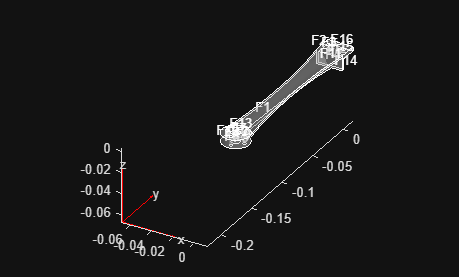

pdegplot(tArmMd,FaceLabels="on",FaceAlpha=0.3);


% This section assigns the material properties for the drone arm. We can
% loop it to see the material properties for the 6 materials we were given.
% Type featarmResults into the command window to view the max
% stress, displacement, and factor of safety for the various materials.
featarmResults = table();

for m = 1:numel(materials)
    mat = materials(m);
    tArmMd.MaterialProperties = materialProperties(PoissonsRatio = mat.nu, YoungsModulus= mat.E_Pa, MassDensity= mat.rho_kg_m3);

    tArmMd.FaceBC(5) = faceBC(Constraint="fixed"); %makes drone mount fixed
    tArmMd.CellLoad = cellLoad(Gravity=[0 0 -g]); %makes drone arm experience gravity
    motorWeight = 0.105 * g;
    thrustForce = thrustMotor * g;
    netForce = thrustForce - motorWeight;
    tArmMd.FaceLoad(13) = faceLoad(SurfaceTraction = [0 0 (netForce/0.000424115)]); %makes the drone arm experience thrust from motor

    sol = solve(tArmMd); % completes the FEA (remove semicolon to view)

    maxStress = max(sol.VonMisesStress);
    maxDisplacement = max(sol.Displacement.Magnitude);
    factorOfSafety = mat.yieldStrength_Pa/maxStress; %checks Factor of Safety

    featarmResults = [featarmResults; table(string(mat.name),sol ,maxStress, maxDisplacement, factorOfSafety, 'VariableNames', {'Material','FEASolution' ,'MaxStress','MaxDisplacement (Z)','FactorOfSafety'})];
end

% clear temporary vars
clearvars m mat maxDisplacement maxStress factorOfSafety motorWeight thrustForce netForce maxStress maxDisplacement factorOfSafety sol



% This section displays our gathered information, just showing the data
% and visualizing it through graphs and figures.
beamResults

beamResults = 6×4 table
               Material                ArmMass_kg    MaxPayload_kg    MeetsMin
    _______________________________    __________    _____________    ________

    "Carbon Fiber Composite (CFRP)"      0.19963        0.80037        true   
    "Aluminum Alloy"                     0.33687        0.66313        true   
    "Fiberglass Composite (GFRP)"        0.23706        0.76294        true   
    "PLA Plastic"                        0.15596        0.84404        true   
    "ABS Plastic"                        0.13101        0.86899        true   
    "Wood (Birch)"                      0.074861        0.92514        true   


tarmResults

tarmResults = 6×4 table
               Material                ArmMass     MaxPayload    MeetsMin
    _______________________________    ________    __________    ________

    "Carbon Fiber Composite (CFRP)"      0.1054      0.8946       true   
    "Aluminum Alloy"                    0.17787     0.82213       true   
    "Fiberglass Composite (GFRP)"       0.12517     0.87483       true   
    "PLA Plastic"                      0.082346     0.91765       true   
    "ABS Plastic"                      0.069171     0.93083       true   
    "Wood (Birch)"                     0.039526     0.96047       true   



featubeResults

featubeResults = 6×5 table
               Material                          FEASolution              MaxStress     MaxDisplacement (Z)    FactorofSafety
    _______________________________    _______________________________    __________    ___________________    ______________

    "Carbon Fiber Composite (CFRP)"    1×1 pde.StaticStructuralResults    4.9496e+06        5.5033e-05             121.22    
    "Aluminum Alloy"                   1×1 pde.StaticStructuralResults    4.8347e+06        5.4826e-05              56.88    
    "Fiberglass Composite (GFRP)"      1×1 pde.StaticStructuralResults    4.9356e+06        0.00015339             60.783    
    "PLA Plastic"                      1×1 pde.StaticStructuralResults    4.9357e+06         0.0011056             12.156    
    "ABS Plastic"                      1×1 pde

featarmResults

featarmResults = 6×5 table
               Material                          FEASolution              MaxStress     MaxDisplacement (Z)    FactorOfSafety
    _______________________________    _______________________________    __________    ___________________    ______________

    "Carbon Fiber Composite (CFRP)"    1×1 pde.StaticStructuralResults    1.5252e+07        0.00046495              39.34    
    "Aluminum Alloy"                   1×1 pde.StaticStructuralResults    1.5145e+07         0.0004675             18.158    
    "Fiberglass Composite (GFRP)"      1×1 pde.StaticStructuralResults    1.5224e+07         0.0012999             19.706    
    "PLA Plastic"                      1×1 pde.StaticStructuralResults    1.5282e+07         0.0092936             3.9261    
    "ABS Plastic"                      1×1 pde

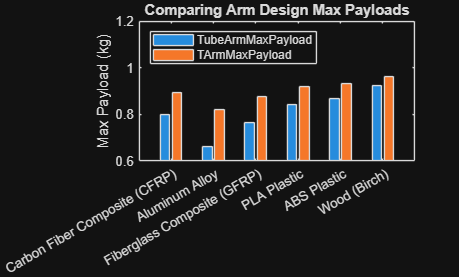


% create Max Payload Bar Graph

bar(beamResults.Material,[beamResults.MaxPayload_kg,tarmResults.MaxPayload])
ylim([.6 1.2])
ylabel("Max Payload (kg)")
legend(Location="northwest",String=["TubeArmMaxPayload", "TArmMaxPayload"])
title("Comparing Arm Design Max Payloads")

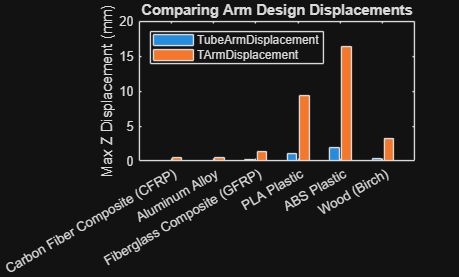


% create Displacement Bar Graph
TubeArmDisplacement = featubeResults.("MaxDisplacement (Z)") * 1000;
TArmDisplacement = featarmResults.("MaxDisplacement (Z)") * 1000;
bar(featubeResults.Material,[ TubeArmDisplacement,TArmDisplacement])
ylabel("Max Z Displacement (mm)")
legend(Location="northwest",String=["TubeArmDisplacement", "TArmDisplacement"])
title("Comparing Arm Design Displacements")

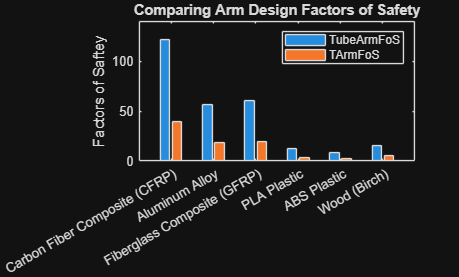


% Clear temp vars
clearvars TubeArmDisplacement TArmDisplacement

% create Factor of Safety Bar Graph
bar(featubeResults.Material,[featubeResults.FactorofSafety,featarmResults.FactorOfSafety])
ylabel("Factors of Saftey")
legend(Location="northeast",String=["TubeArmFoS", "TArmFoS"])
title("Comparing Arm Design Factors of Safety")

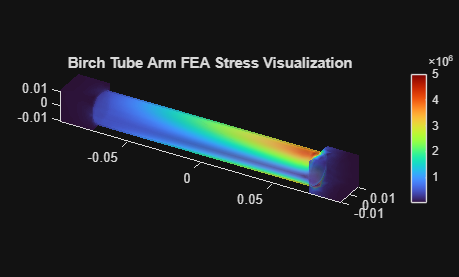



% Data to visualize
TArmBirchFEA = featarmResults.FEASolution(6);
meshData = TArmBirchFEA.Mesh;
nodalData = TArmBirchFEA.VonMisesStress;
deformationData = TArmBirchFEA.Displacement;

TubeArmBirchFEA = featubeResults.FEASolution(6);
meshData2 = TubeArmBirchFEA.Mesh;
nodalData2 = TubeArmBirchFEA.VonMisesStress;
deformationData2 = TubeArmBirchFEA.Displacement;

% Create PDE result visualizations
resultViz = pdeviz(meshData2,nodalData2, ...
    "DeformationData",deformationData2, ...
    "DeformationScaleFactor",0, ...
    "ColorLimits",[1.664e-11 5000000], ...
    "Transparency",0.61,...
    "Title","Birch Tube Arm FEA Stress Visualization");

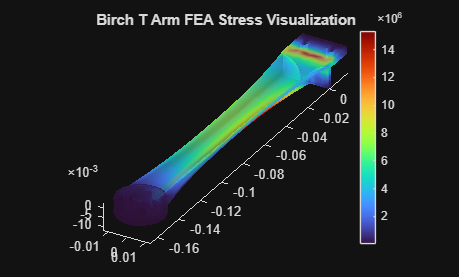


resultViz2 = pdeviz(meshData,nodalData, ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",0, ...
    "ColorLimits",[4609 15350000], ...
    "Transparency",0.61,...
    "Title","Birch T Arm FEA Stress Visualization");


% Clear temporary variables
clearvars meshData nodalData deformationData meshData2 nodalData2 deformationData2